# Projekt 1

### Zadanie 1:

disp('Zadanie 1:')

Zadanie 1:


symulacja_obiektu15Y_p1(1.2,1.2,2,2)

ans = 2

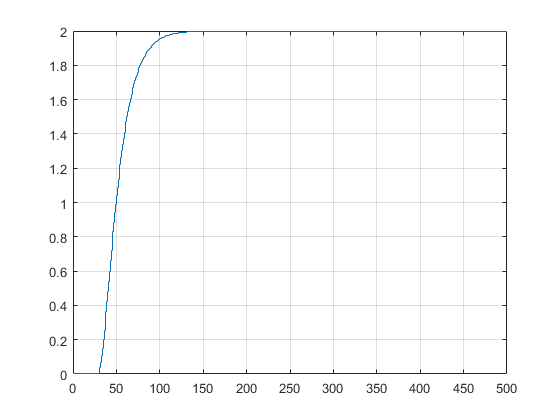

SIM_LENGHT = 500;
Upp = 1.2;
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
U(:) = 1.2;
U(50:end) = 1.2;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
        U(k-11), Y(k-1), Y(k-2));
end
stairs(Y)
grid


writematrix(Y, 'p1_zadanie1.csv')

### Zadanie 2:

disp('Zadanie 2:')

Zadanie 2:


Wyznaczyć symulacyjnie odpowiedzi skokowe procesu dla kilku zmian sygnału sterującego, przy uwzględnieniu ograniczeń wartości tego sygnału, jego wartość na początku eksperymentu wynosi Upp.  Narysować te odpowiedzi na jednym rysunku.

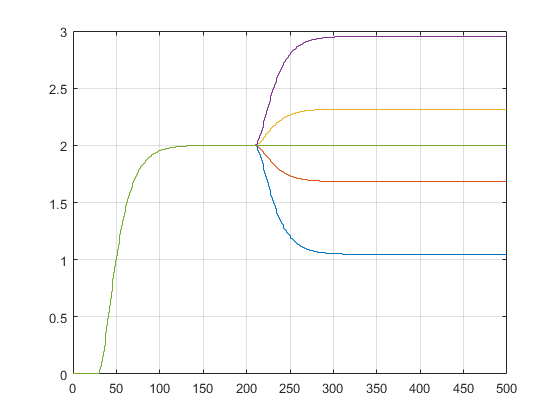

U_zad_zmiany = [0.9, 1.1, 1.3, 1.5, 1.2];
Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
SIM_LENGHT = 500;
STEP_MOMENT = 200;
Upp = 1.2;
U(:) = Upp;


for p=1:length(U_zad_zmiany)
    U(200:end) = U_zad_zmiany(p);
    for k=30:SIM_LENGHT
        Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
            U(k-11), Y(k-1), Y(k-2));
    end
    stairs(Y)
    hold on
end


grid on
hold off

Narysować charakterystykę statyczną procesu y(u). Czy właściwości statyczne i dynamiczne procesu są (w przybliżeniu) liniowe? Jeżeli tak, określić wzmocnienie statyczne procesu.

disp('Charakterystyka statyczna:')

Charakterystyka statyczna:


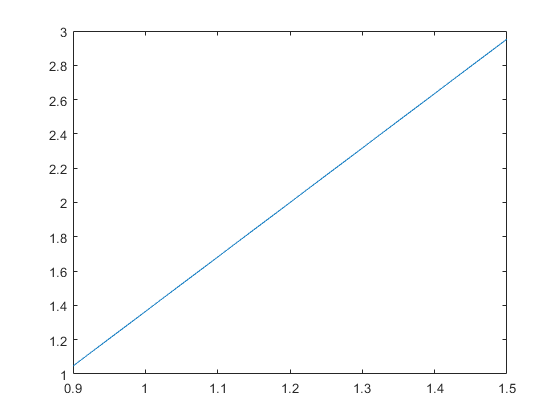

Y_stat = zeros(100,1);

U_zad = linspace(0.9, 1.5, 100)';
for i = 1:length(U_zad)
    [Y, U] = get_YU(1.2, U_zad(i), SIM_LENGHT, STEP_MOMENT);
    Y_stat(i)= Y(SIM_LENGHT);
end
plot(U_zad, Y_stat)

Wzmocnienie statyczne to wspolczynnik kierunkowy prostej z wykresu

delta_y = Y_stat(50)-Y_stat(20);
delta_u = U_zad(50)-U_zad(20);
Wzm_stat = delta_y/delta_u

Wzm_stat = 3.1778

### Zadanie 3:

Przekształcić jedną z otrzymanych odpowiedzi w taki sposób, aby otrzymać odpowiedź skokową wykorzystywaną w algorytmie DMC, tzn. zestaw liczb s1, s2, . . . (przy skoku jednostkowym sygnału sterującego: od chwili k = 0 włącznie sygnał sterujący ma wartość 1, w przeszłości jest zerowy). Zamieścić rysunek odpowiedzi skokowej

disp('Zadanie 3:')

Zadanie 3:


% symulacja_obiektu15Y_p1(0.9,0.9,1.047,1.047)
% symulacja_obiektu15Y_p1(1,1,1.047,1.047)

SIM_LENGHT = 500;
STEP_MOMENT = 300

STEP_MOMENT = 300

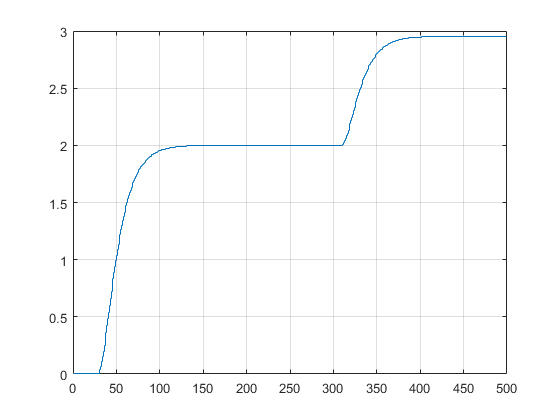

Y = zeros(SIM_LENGHT,1);
U = zeros(SIM_LENGHT,1);
U(:) = 1.2;
U(STEP_MOMENT:end) = 1.5;
for k=30:SIM_LENGHT
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), ...
        U(k-11), Y(k-1), Y(k-2));
end
stairs(Y)
% hold on
% stairs(U, "--")
grid on

Przeksztalcenie odpowiedzi skokowej - to o czym mowil Ławryńczuk na drugich ćwiczeniach

Wektor s ze współczynnikami s1, s2, ...

deltaU = 1.5-1.2

deltaU = 0.3000


% U_przeksztalcone = U(STEP_MOMENT:end)
s = Y(STEP_MOMENT:end);
s = (s-2.0)/deltaU

s =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


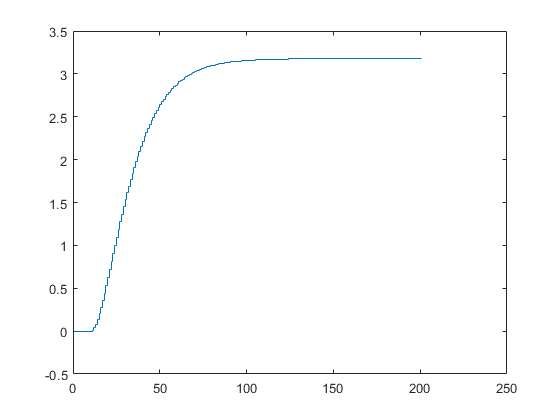


stairs(s)

% hold on
% stairs(U_przeksztalcone)


### Zadanie 4

Napisać i omówić program w języku MATLAB do symulacji cyfrowego algorytmu PID oraz algorytmu DMC (w najprostszej wersji analitycznej) dla symulowanego procesu. Istniejące ograniczenia wartości sygnału sterującego oraz ograniczenie szybkości zmian tego sygnału

 −deltaU max <= deltaU(k) <=deltaU max

 gdzie 4U max = 0,25, uwzględnić odpowiednio ograniczając (przycinając) wyznaczony przez regulator sygnał sterujący

deltaUmax = 0.25;



### Zadanie 5

DMC

lambda = 0.001;
N = 50;
Nu = 50;
MV_MIN = 0.9;
MV_MAX = 1.5;
dMV_MIN = -0.25;
dMV_MAX = 0.25;

% SIM_LENGHT=2000;

controllerDMC = DMC(s, lambda, N, Nu, MV_MIN, MV_MAX, dMV_MIN, dMV_MAX);
controllerPID = PID(0.60, 14, 5, 0.5, MV_MIN, MV_MAX, dMV_MIN, dMV_MAX);

Kkrytyczne = 0.975

T = 55

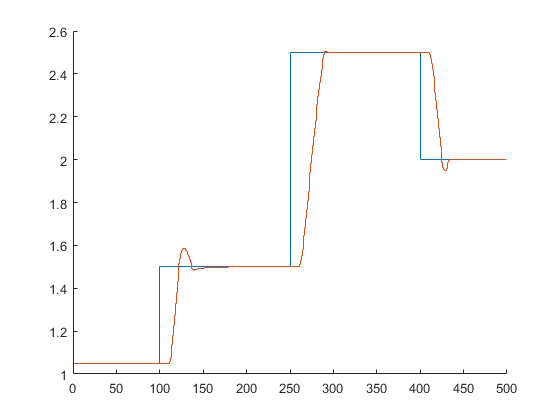


y_zad = ones(SIM_LENGHT,1)*1.047;
Y_dmc = ones(SIM_LENGHT,1)*1.047;
Y_pid = ones(SIM_LENGHT,1)*1.047;
U_dmc = ones(SIM_LENGHT,1)*0.9;
U_pid = ones(SIM_LENGHT,1)*0.9;

y_zad(100:SIM_LENGHT) = 1.5;
y_zad(250:400) = 2.5;
y_zad(400:500) = 2;


for k=30:SIM_LENGHT
    U_dmc(k) = controllerDMC(y_zad(k) - Y_dmc(k-1));
    U_pid(k) = controllerPID(y_zad(k) - Y_pid(k-1));
    
    Y_dmc(k) = symulacja_obiektu15Y_p1(U_dmc(k-10), ...
        U_dmc(k-11), Y_dmc(k-1), Y_dmc(k-2));
    
    Y_pid(k) = symulacja_obiektu15Y_p1(U_pid(k-10), ...
        U_pid(k-11), Y_pid(k-1), Y_pid(k-2));
end
figure
hold on
stairs(y_zad)
stairs(Y_dmc)
hold off

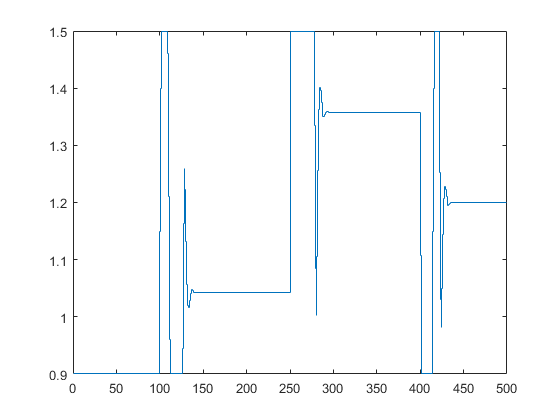

stairs(U_dmc)

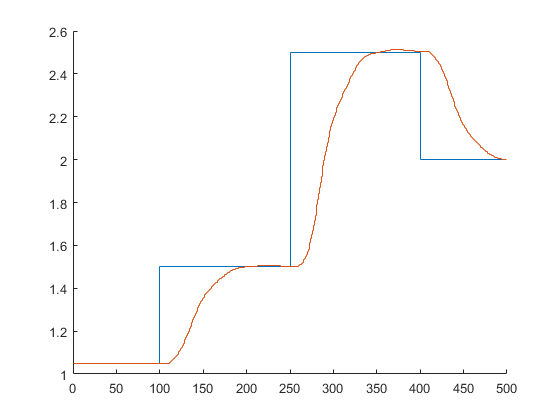


figure
hold on
stairs(y_zad)
stairs(Y_pid)
hold off

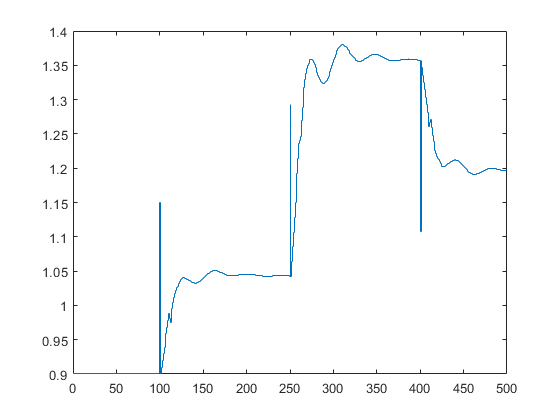

stairs(U_pid)


err = norm(y_zad-Y_dmc);
display(err)

err = 5.3204

PID

#### FUNKCJE:

Funkcja Piotra do wyznaczania odpowiedzi skokowych

function [Y, U] = get_YU(U_pp, U_zad, sim_lenght, step_moment)
Y = zeros(sim_lenght,1);
U = zeros(sim_lenght,1);
U(:) = U_pp;
U(step_moment:end) = U_zad;
for k=30:sim_lenght
    Y(k) = symulacja_obiektu15Y_p1(U(k-10), U(k-11), Y(k-1), Y(k-2));
end
end
